# TrainingB Algorithm

Trains a deep network following this example:

[https://www.mathworks.com/help/deeplearning/examples/object-detection-using-yolo-v2.html](https://www.mathworks.com/help/deeplearning/examples/object-detection-using-yolo-v2.html)

However, this version uses resnet18 and adds a YOLO network at one of the later layers. It uses 224x224 images

Data not included here. Too many images to store on GitHub. The plate location was determined in each frame by findByImgProcessingA.m (in models\) and then checked and brushed up with the VideoLabeler App (from MathWorks). The videos were split into many images. The location of the plate was encoded in the filename of the image. This training algorithm loads the images, gets the plate location from the filename, and then trains the network by supervised learning.

## Create list of image file names and plate locations

Get file names (make sure you are in the folder where Frames is located. Maybe create a check for this?

if ~endsWith(pwd,"training")
    error("For training, change directory to \training")
end
files = dir("Frames\*.tif");                % get all tif files
files = string({files.name});               % convert to string
files(startsWith(files,"label")) = [];      % drop duplicates starting with "label"

Get plate location from file name

for n = 1:length(files)
    file = files(n);
    x = double(extractBetween(file,4,6));
    y = double(extractBetween(file,7,9));
    w = double(extractBetween(file,10,12));
    h = double(extractBetween(file,13,15));
    pos(n) = {[x y w h]};
end

Put it all together

files = "Frames\" + files;
data = table(files', pos', 'VariableNames',["filename" 'plate']);

## Split data into training and testing sets

rng(0);                                                 % reset random seed
shuffledIndices = randperm(height(data));               % probably didn't need to randomize earlier:)
idx = floor(0.3 * length(shuffledIndices) );            % 30% for training
endTesting = length(shuffledIndices);                   % use length(shuffledIndices)

% use a smaller set for testing
idx = floor(0.02 * length(shuffledIndices) );           % use 0.6% (or 0.02 to be fast)
endTesting = 2*idx;     %length(shuffledIndices);       % use length(shuffledIndices)

trainingData = data(shuffledIndices(1:idx),:);
testData = data(shuffledIndices(idx+1:endTesting),:);


## Create datastores to manage the data

imgsTrain = imageDatastore(trainingData{:,'filename'});
posTrain = boxLabelDatastore(trainingData(:,'plate'));

imgsTest = imageDatastore(testData{:,'filename'});
posTest = boxLabelDatastore(testData(:,'plate'));

% Combine image and box label datastores.
trainingData = combine(imgsTrain,posTrain);
testData = combine(imgsTest,posTest);

## Check one of the images

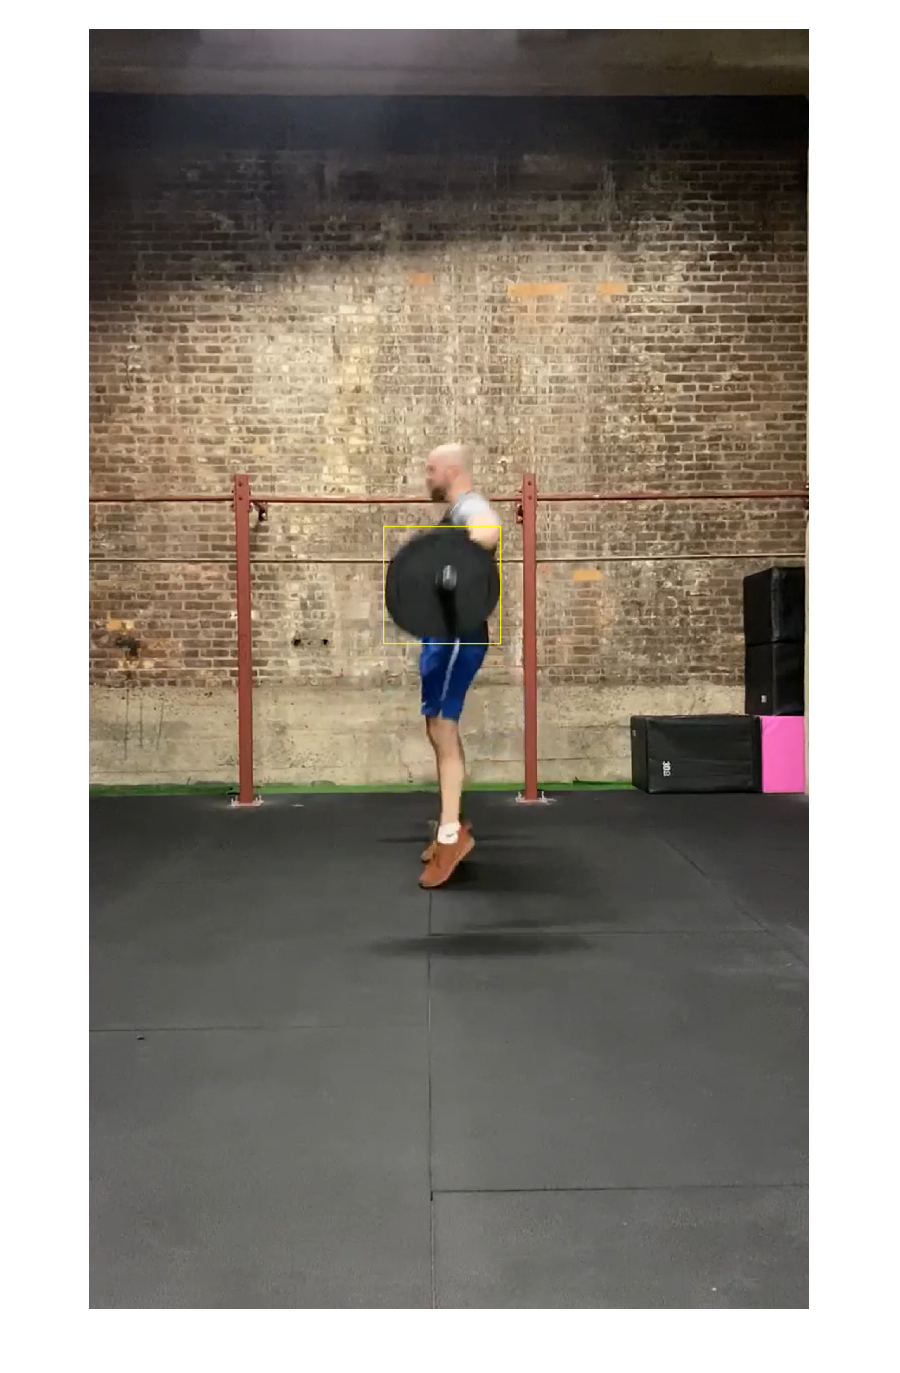

data = read(trainingData);
I = data{1};
bbox = data{2};
annotatedImage = insertShape(I,'Rectangle',bbox);
annotatedImage = imresize(annotatedImage,2);
figure
imshow(annotatedImage)

## Create YOLO v2 Object Detection Network

inputSize = [224 224 3];    % use resnet18 size
numClasses = 1;             % only one class: plate, no plate
% estimate the number of anchor boxes (maybe play with this later given the
% narrow range on plate sizes)
trainingDataForEstimation = transform(trainingData,@(data)preprocessData(data,inputSize));
numAnchors = 7;
[anchorBoxes, meanIoU] = estimateAnchorBoxes(trainingDataForEstimation, numAnchors)

anchorBoxes =     22    38
    21    37
    21    38
    22    37
    21    38
    21    38
    22    37


meanIoU = 1.0000

% specify the featureExtractionNetwork
featureExtractionNetwork = resnet18;
% specify layer to start detection network
featureLayer = 'res4b_relu';    % not sure what layer to choose. Will try this one (2 prior to fully connected layer)
% create the YOLO detection network
lgraph = yolov2Layers(inputSize,numClasses,anchorBoxes,featureExtractionNetwork,featureLayer);

## Data Augmentation - flip images to add variety

augmentedTrainingData = transform(trainingData,@augmentData);
preprocessedTrainingData = transform(augmentedTrainingData,@(data)preprocessData(data,inputSize));

## Training

options = trainingOptions('sgdm', ...
        'MiniBatchSize', 16, ....
        'InitialLearnRate',1e-3, ...
        'MaxEpochs',8,...                   % was 20
        'CheckpointPath', tempdir, ...
        'Shuffle','never');

save('trainingData.mat')
disp("Done with data prep; start training")

Done with data prep; start training


[detector,info] = trainYOLOv2ObjectDetector(preprocessedTrainingData,lgraph,options);

*************************************************************************
Training a YOLO v2 Object Detector for the following object classes:

* plate

Training on single CPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:02 |         9.39 |         88.2 |          0.0010 |
|       8 |           8 |       00:00:25 |         0.95 |          0.9 |          0.0010 |
|========================================================================================|
Detector training complete.
*************************************************************************



save('trained.mat')

## Check result at low resolution

%load('trainedWithResNet18.mat');
data = read(testData);
I = data{1};
I = imresize(I,inputSize(1:2));
tic
[bboxes,scores] = detect(detector,I);
toc

Elapsed time is 0.779542 seconds.


if ~isempty(bboxes)
    I = insertObjectAnnotation(I,'rectangle',bboxes,scores);
    imshow(I)
else
    disp('Empty! Plate not found!')
end

Empty! Plate not found!


## Check result with full resolution

smallSize = detector.TrainingImageSize;
data = read(testData);
I = data{1};
origSize = size(I,1:2);
Ismall = imresize(I,inputSize(1:2));
[bboxes,scores] = detect(detector,Ismall);
if ~isempty(bboxes)
    [~,idx] = max(scores);
    box = bboxes(idx,1:4);
    frameSmall = insertShape(Ismall,'Rectangle',box,'LineWidth',5,'Color',{"yellow"});
    imshow(frameSmall)
    x = box(1) * origSize(2)/smallSize(2);
    y = box(2) * origSize(1)/smallSize(1);
    w = box(3) * origSize(2)/smallSize(2);
    h = box(4) * origSize(1)/smallSize(1);
    frame = insertShape(I,'Rectangle',[x y w h],'LineWidth',5,'Color',{"yellow"});
    imshow(frame)
else
    disp('empty!')
end

empty!


## Supporting Functions

function B = augmentData(A)
% Apply random horizontal flipping, and random X/Y scaling. Boxes that get
% scaled outside the bounds are clipped if the overlap is above 0.25. Also,
% jitter image color.
B = cell(size(A));

I = A{1};
sz = size(I);
if numel(sz)==3 && sz(3) == 3
    I = jitterColorHSV(I,...
        'Contrast',0.2,...
        'Hue',0,...
        'Saturation',0.1,...
        'Brightness',0.2);
end

% Randomly flip and scale image.
tform = randomAffine2d('XReflection',true,'Scale',[1 1.1]);
rout = affineOutputView(sz,tform,'BoundsStyle','CenterOutput');
B{1} = imwarp(I,tform,'OutputView',rout);

% Apply same transform to boxes.
[B{2},indices] = bboxwarp(A{2},tform,rout,'OverlapThreshold',0.25);
B{3} = A{3}(indices);

% Return original data only when all boxes are removed by warping.
if isempty(indices)
    B = A;
end
end

function data = preprocessData(data,targetSize)
% Resize image and bounding boxes to the targetSize.
scale = targetSize(1:2)./size(data{1},[1 2]);
data{1} = imresize(data{1},targetSize(1:2));
data{2} = bboxresize(data{2},scale);
end